# Testing the Function SNHT_side_wall

## Simple Test Plane

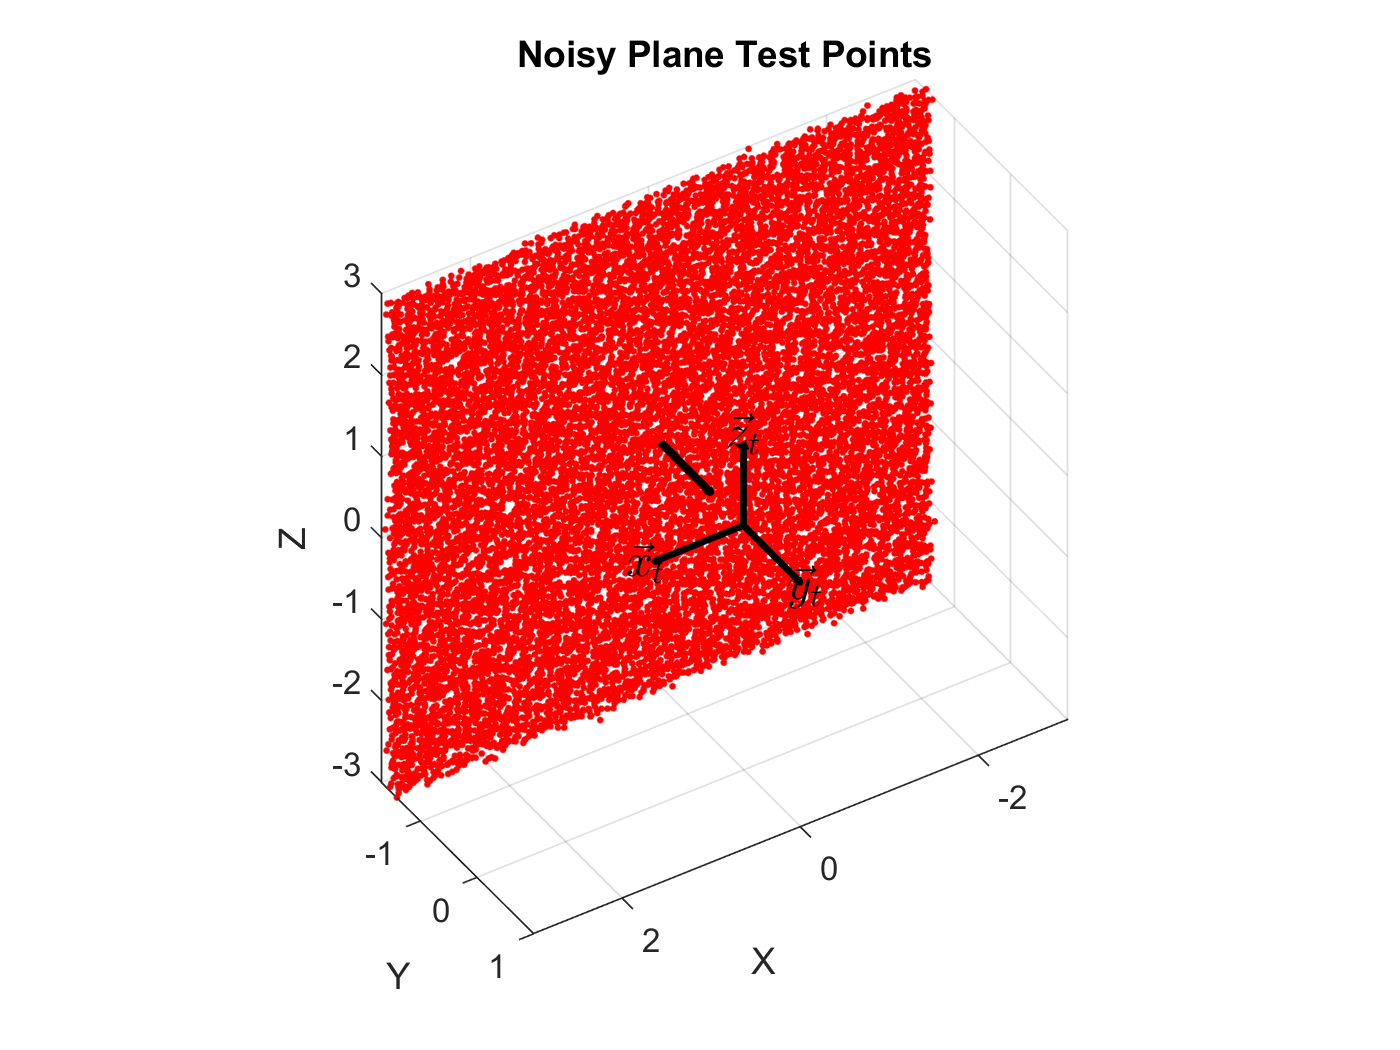

% Build a Somewhat Noisy Test Plane
psi   = 0 * pi/180;
C = rotate_z(psi) * rotate_z(pi/2) * rotate_y(pi/2);
org = [0, -1.5, 0];
dim = 3 * [-1 1; -1 1];
dx = 0.05; dy = 0.05;
sigmas = [0; 0; 0.05];
color = 'r';

% Generate Point Cloud using the Same Parameters
xyz = gen_plane(C, org, dim, dx, dy, sigmas);

figure
hold on
plot_plane(C, org, dim, dx, dy, sigmas, color);
plot_frame(eye(3), zeros(3,1), 't', 'k');
quiver3(org(1), org(2), org(3), cos(psi + pi/2), sin(psi + pi/2), 0, 'k', 'LineWidth', 2.5)
title('Noisy Plane Test Points')
xlabel('X')
ylabel('Y')
zlabel('Z')
% xlim([-1 3])
% ylim([-1 1])
% zlim([-1.5 1.5])
view([147.66 39.39])
axis equal
grid on
hold off

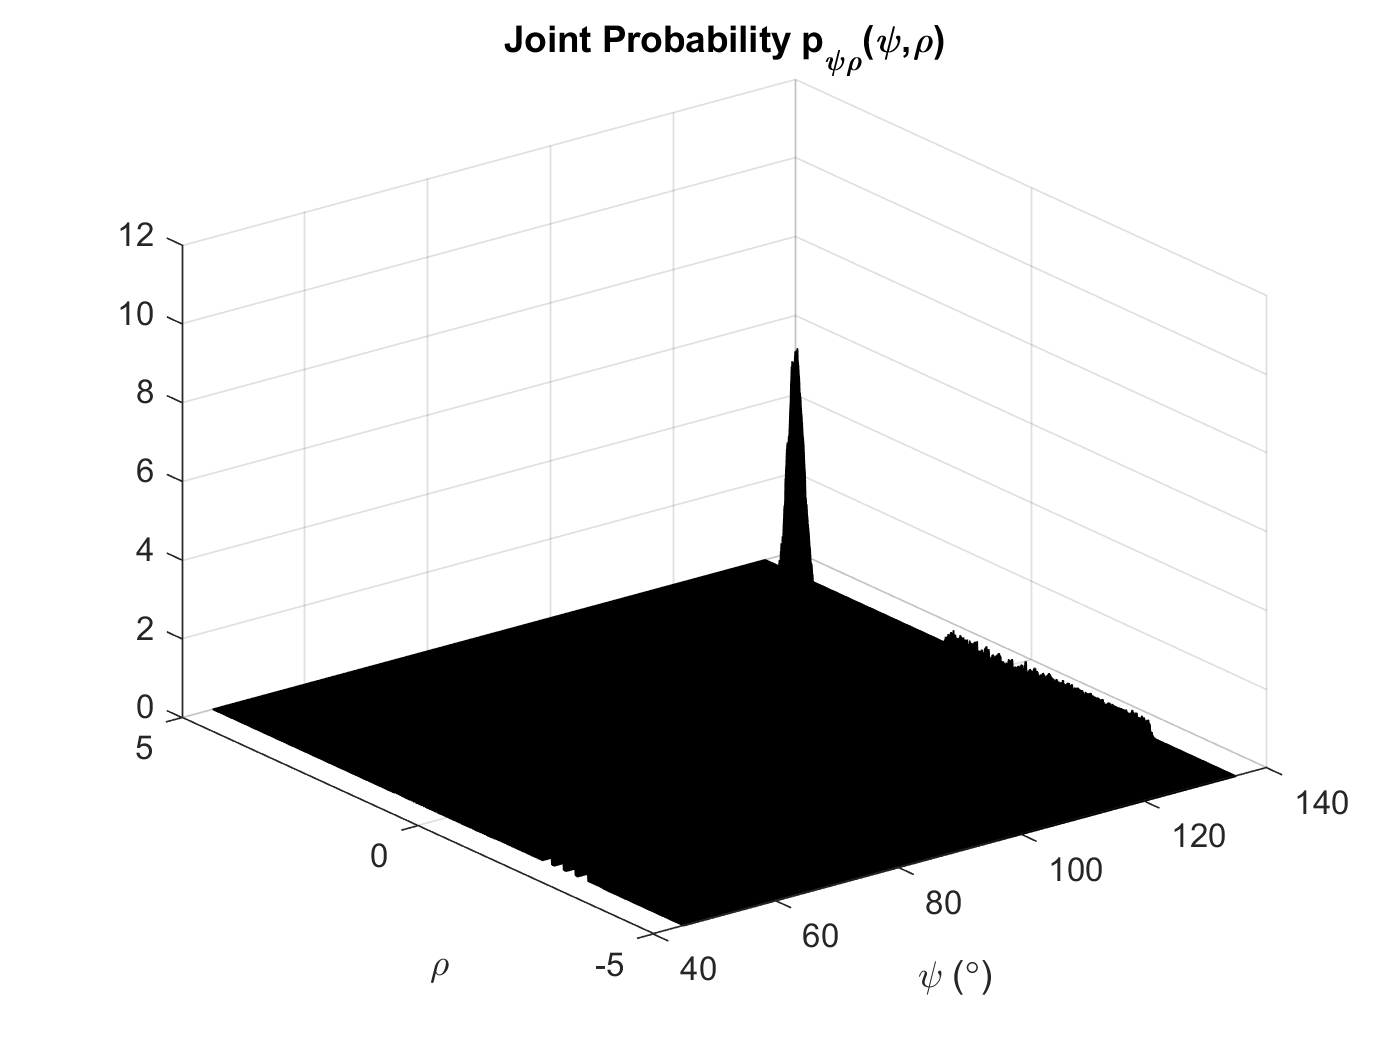

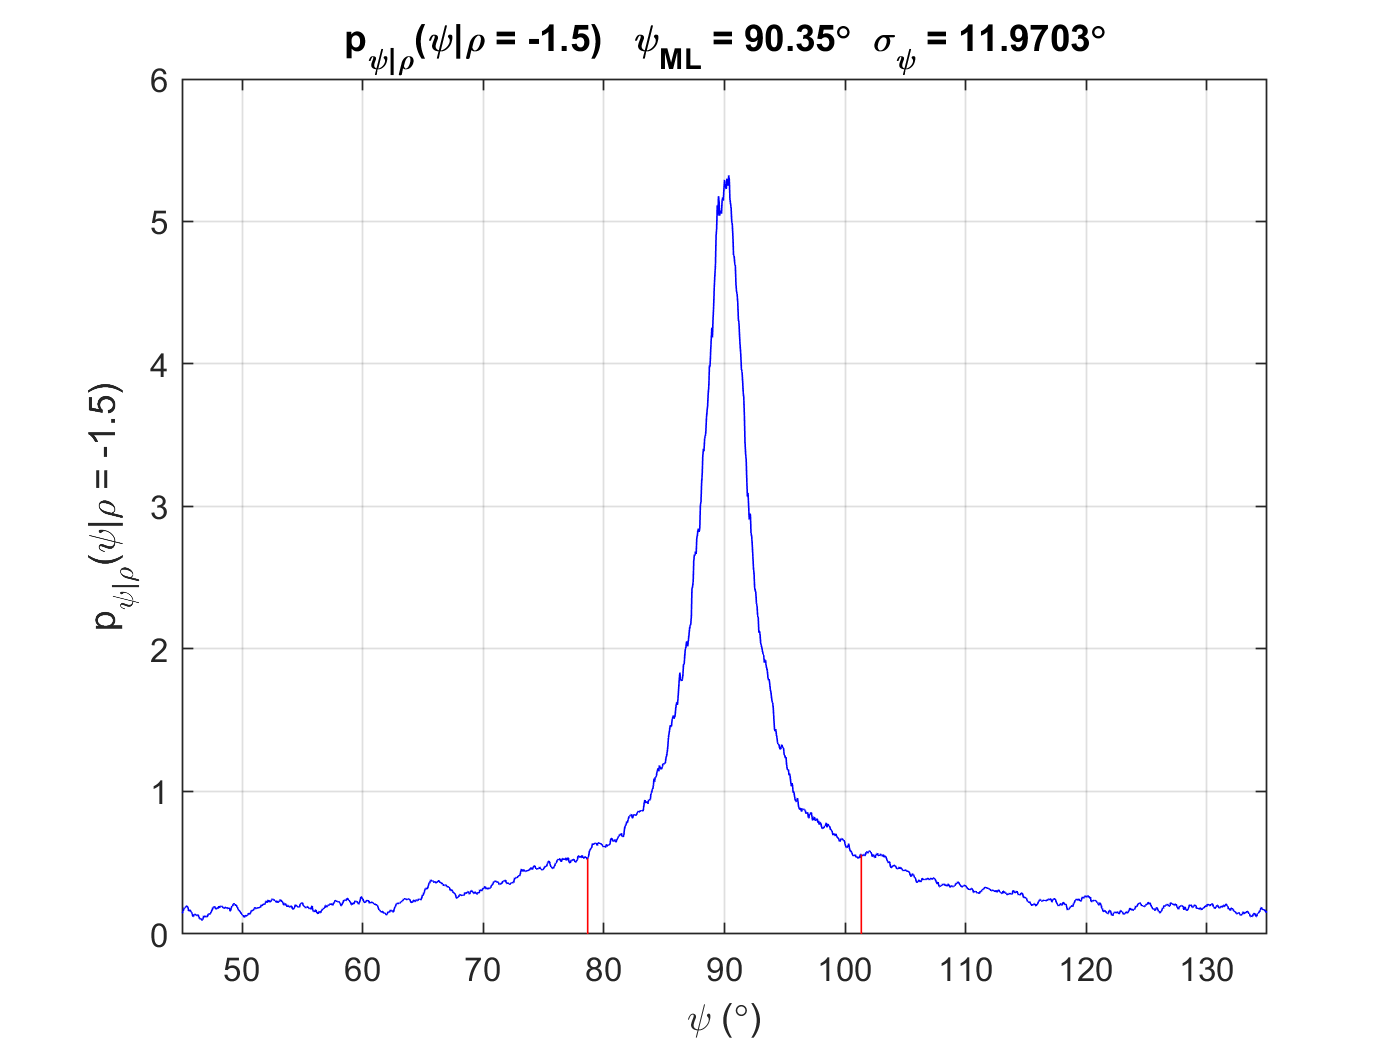

% Test the Algorithm
psi_settings = [45, 0.05, 135] * pi/180;   % radians
plot_flag = true;
[psi_mode, psi_var] = SNHT_side_wall(xyz, psi_settings, plot_flag);